# Loading Data

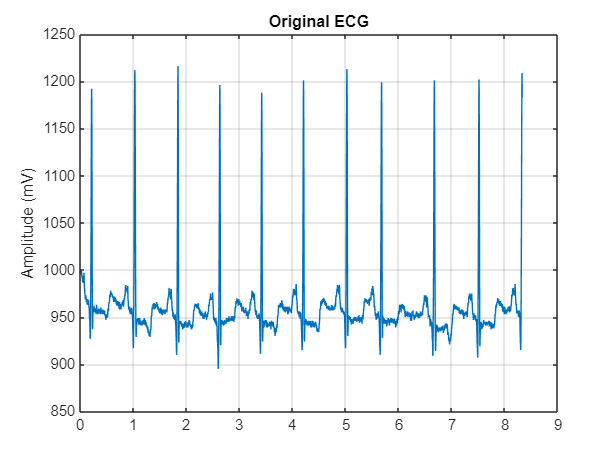

clc;
clear;
close all;


data = readmatrix('100.csv');
x = data(:,2);
x = x(:);
N = length(x);

fs = 360;
t = (0:N-1)/fs;


figure;
plot(t(1:3000), x(1:3000))
title('Original ECG')
ylabel('Amplitude (mV)')
grid on

# Adding Noise 

x_mean = mean(x);

% Wavelet Filters 
phi = [0.5 1 0.5];
psi = [1 0 -1];
phi = phi / norm(phi);
psi = psi / norm(psi);
L = length(phi);

levels = 3;   

% Noise levels
noise_levels = [0.1 0.25 0.4 0.6 0.8];

# Evaluation of Noise Removal Capability and Reconstruction

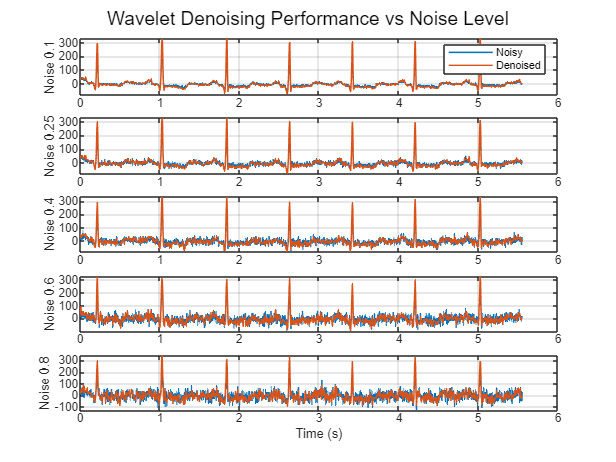

figure;
sgtitle('Wavelet Denoising Performance vs Noise Level')

for j = 1:length(noise_levels)

    %% Add Noise
    K = noise_levels(j);
    noise = K * std(x) * randn(size(x));
    x_noisy = (x - x_mean) + noise;

    %% Decomposition
    x_level = x_noisy;
    cA = cell(levels,1);
    cD = cell(levels,1);

    for i = 1:levels
        len = length(x_level);
        tempA = zeros(len,1);
        tempD = zeros(len,1);

        for k = 1:len
            for n = 1:L
                idx = k + n - 1;
                if idx <= len
                    tempA(k) = tempA(k) + x_level(idx)*phi(n);
                    tempD(k) = tempD(k) + x_level(idx)*psi(n);
                end
            end
        end

        cA{i} = tempA(1:2:end);
        cD{i} = tempD(1:2:end);
        x_level = cA{i};
    end

    %% Soft Thresholding
    for i = 1:levels
        sigma = median(abs(cD{i})) / 0.6745;
        lambda = sigma * sqrt(2*log(length(cD{i})));
        cD{i} = sign(cD{i}) .* max(abs(cD{i}) - lambda, 0);
    end

    %% Reconstruction
    for i = levels:-1:1
        len = length(cA{i});
        x_rec = zeros(len*2,1);

        for k = 1:len
            for n = 1:L
                idx = 2*k + n - 2;
                if idx <= length(x_rec)
                    x_rec(idx) = x_rec(idx) + cA{i}(k)*phi(n) + cD{i}(k)*psi(n);
                end
            end
        end

        cA{i} = x_rec;
    end

    x_denoised = x_rec(1:N);

    %% Plot Results
    subplot(length(noise_levels),1,j)
    plot(t(1:2000), x_noisy(1:2000),'LineWidth', 1); hold on
    plot(t(1:2000), x_denoised(1:2000), 'LineWidth', 1);
    ylabel(['Noise ', num2str(K)])
    grid on
    if j == 1
        legend('Noisy','Denoised')
    end

end

xlabel('Time (s)')